figopts.Color = "none";

XLabelopts.FontSize = 18;
XLabelopts.Interpreter = "latex";
YLabelopts.FontSize = 18;
YLabelopts.Interpreter = "latex";

axopts.FontSize = 14;
axopts.Box = "on";
axopts.FontName = "Times";  % "LiberationSerif"
axopts.Color = "none";

lgdopts.Location = "best";
lgdopts.FontSize = 14;
lgdopts.FontName = "Times";
lgdopts.Interpreter = "latex";
lgdopts.box = "off";

% % 参数设置
% fs = 50*12; % 载波频率 (Hz)
% fm = 50; % 调制波频率 (Hz)
% M = 10; % 载波的调制倍数
% Am = .9; % 调制波幅值
% Ac = 1; % 载波幅值
% T = 1 / fm; % 调制波的周期
% t = 0:1/(fs*100):T; % 时间向量，1.5 个周期
% 
% % 正弦调制波生成
% mod_wave = Am * sin(2*pi*fm*t);
% 
% % 生成四个偏移的三角载波
% triangle_wave1 = Ac * sawtooth(2*pi*fs*t, 0.5); % 第一个载波
% % triangle_wave2 = Ac * sawtooth(2*pi*fs*t - pi/2, 0.5); % 第二个载波，偏移 45°
% % triangle_wave3 = Ac * sawtooth(2*pi*fs*t - pi, 0.5); % 第三个载波，偏移 90°
% % triangle_wave4 = Ac * sawtooth(2*pi*fs*t - 3*pi/2, 0.5); % 第四个载波，偏移 135°
% 
% % 生成 Gate Signal
% gate_signal1 = mod_wave > triangle_wave1; % Gate 信号 1
% % gate_signal2 = mod_wave > triangle_wave2; % Gate 信号 2
% % gate_signal3 = mod_wave > triangle_wave3; % Gate 信号 3
% % gate_signal4 = mod_wave > triangle_wave4; % Gate 信号 4
% 
% % 绘图
% fig = figure;
% set(fig, figopts);
% 
% tiledlayout(2, 1);
% 
% % 绘制调制波和载波
% ax1 = nexttile;
% grid on
% hold on;
% 
% 
% plot(t, triangle_wave1, Color='k', LineWidth=2);
% % plot(t, triangle_wave2, Color='g', LineWidth=1);
% % plot(t, triangle_wave3, Color='b', LineWidth=1);
% % plot(t, triangle_wave4, Color='m', LineWidth=1);
% plot(t, mod_wave, Color='b', LineWidth=2);
% % title('Modulation Wave and Carriers');
% % xlabel('Time [s]');
% ylabel('Amplitude [/]');
% ylim([-1.2, 2.4]);
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% label = ["Carrier", "Modulation Wave"];
% lgd = legend(label, NumColumns=2);
% set(lgd, lgdopts)
% 
% ax2 = nexttile;
% grid on
% hold on
% plot(t, gate_signal1, Color='k', LineWidth=2);
% % plot(t, gate_signal2, Color='g', LineWidth=1.5);
% % plot(t, gate_signal3, Color='b', LineWidth=1.5);
% % plot(t, gate_signal4, Color='m', LineWidth=1.5);
% 
% xlabel('Time [s]');
% ylabel('Amplitude [/]');
% ylim([-.2, 1.5]);
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% label = ["Gate Signal"];
% lgd = legend(label, NumColumns=4);
% set(lgd, lgdopts)
% lgd.Location = "northeast";
% 
% linkaxes([ax1, ax2], "x")
% 
% exportgraphics(gcf, "./fig/pwm.eps");

% Y = fft(gate_signal1);
% f = fs / length(gate_signal1) * 0: ceil(length(gate_signal1)/2);
% P2 = abs(Y/length(gate_signal1));
% P1 = P2(1: ceil(length(gate_signal1)/2));
% P1(2:end-1) = 4*P1(2:end-1);
% P1(1) = 0;
% 
% fig = figure;
% set(fig, figopts);
% 
% bar(f(1:12*4), P1(1:12*4), 'k')
% grid on
% 
% xlabel('Frequency [Hz]');
% ylabel('Amplitude [/]');
% ylim([0 0.9])
% yticks([0 .3 .6 .9])
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% annotation("textarrow", [.3 .2], [.85 .85], String="$0.9\,$p.u.", Interpreter="latex", FontSize=14)
% 
% exportgraphics(gcf, "./fig/pwm_spectrum.eps");

function [f, P1] = calcSpectrum(x, Fs)
    L = length(x);                  % 信号长度
    Y = fft(x);                     % 傅里叶变换
    P2 = abs(Y / L);                % 双边频谱幅值
    P1 = P2(1:ceil(L/2));           % 提取单边频谱
    P1(2:end-1) = 2 * P1(2:end-1);  % 修正振幅
    f = Fs * (0:(length(P1)-1)) / L; % 频率轴
end

function thd = calcTHD(P1, f, harmNum)
    % 基波频率（假设基波为最大幅值点）
    [~, idxBase] = max(P1);
    fBase = f(idxBase);

    % 基波功率
    P_base = P1(idxBase);

    % 谐波功率
    harmPowers = zeros(1, harmNum-1);
    for n = 2:harmNum
        fHarm = n * fBase; % 第 n 次谐波频率
        [~, idxHarm] = min(abs(f - fHarm)); % 找到最近的频率索引
        harmPowers(n-1) = P1(idxHarm); % 获取谐波功率
    end

    % 计算 THD
    thd = sqrt(sum(harmPowers.^2)) / P_base;
end

## steady-state

### output voltage and its spectrum

% fig = figure; 
% set(fig, figopts);
% 
% tiledlayout(2, 1)
% 
% t = Vo.time;
% fsample = 1/Ts_Power;
% 
% ax1 = nexttile;  % Vo
% grid on
% hold on
% 
% plot(t(9.6e4: 10e4), Vo.signals.values(9.6e4: 10e4, 1), LineWidth=2, Color='r')
% plot(t(9.6e4: 10e4), Vo.signals.values(9.6e4: 10e4, 2), LineWidth=2, Color='g')
% plot(t(9.6e4: 10e4), Vo.signals.values(9.6e4: 10e4, 3), LineWidth=2, Color='b')
% ylim([-1.2 1.55])
% lgd = legend(["Phase A", "Phase B", "Phase C"], NumColumns=3);
% xlabel("Time [s]")
% ylabel("$V_o$ [p.u.]")
% 
% set(lgd, lgdopts);
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% ax2 = nexttile;  % spectrum
% grid on
% hold on
% 
% [ft, P1] = calcSpectrum(Vo.signals.values(9.6e4: 10e4-1, 1), fsample);
% 
% bar(ft, P1, 'k')
% xlim([0 1500])
% xlabel("Frequency [Hz]")
% ylabel("Amplitude [p.u.]")
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% thd = calcTHD(P1, ft, 1e5);
% annotation("textarrow", [.25 .2], [.35 .32], String="$1.05\,$p.u.", Interpreter="latex", FontSize=14)
% text(800, .7, "THD = $"+sprintf("%.1f",thd*100)+"$\%", Interpreter="latex", FontSize=14)
% exportgraphics(gcf, "./fig/ss/Vo.eps")

### output current and its spectrum

% fig = figure; 
% set(fig, figopts);
% 
% tiledlayout(2, 1)
% 
% t = Vo.time;
% fsample = 1/Ts_Power;
% 
% ax1 = nexttile;  % Io
% grid on
% hold on
% 
% plot(t(9.6e4: 10e4), Io.signals.values(9.6e4: 10e4, 1), LineWidth=2, Color='r')
% plot(t(9.6e4: 10e4), Io.signals.values(9.6e4: 10e4, 2), LineWidth=2, Color='g')
% plot(t(9.6e4: 10e4), Io.signals.values(9.6e4: 10e4, 3), LineWidth=2, Color='b')
% ylim([-.32 .43])
% yticks([-.3 0 .3])
% lgd = legend(["Phase A", "Phase B", "Phase C"], NumColumns=3);
% xlabel("Time [s]")
% ylabel("$I_o$ [p.u.]")
% 
% set(lgd, lgdopts);
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% ax2 = nexttile;  % spectrum
% grid on
% hold on
% 
% [ft, P1] = calcSpectrum(Io.signals.values(9.6e4: 10e4-1, 1), fsample);
% 
% bar(ft, P1, 'k')
% xlim([0 1500])
% xlabel("Frequency [Hz]")
% ylabel("Amplitude [p.u.]")
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% thd = calcTHD(P1, ft, 1e5);
% annotation("textarrow", [.25 .2], [.35 .32], String="$0.30\,$p.u.", Interpreter="latex", FontSize=14)
% text(800, .15, "THD = $"+sprintf("%.1f",thd*100)+"$\%", Interpreter="latex", FontSize=14)
% exportgraphics(gcf, "./fig/ss/Io.eps")

### active power vs frequency

% fig = figure;
% set(fig, figopts);
% 
% tiledlayout(2, 1);
% 
% ax1 = nexttile;  % freq
% t = freq.time;
% data = freq.signals.values;
% grid on
% hold on
% plot(t, data, LineWidth=2, Color='k');
% ylim([49.85 50.2]);
% yticks([49.87, 50, 50.18]);
% % xlabel("Time [s]");
% ylabel("Frequency [Hz]");
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% ax2 = nexttile;  % active power
% data = P.signals.values;
% grid on
% hold on
% 
% plot(t, data, LineWidth=2, Color='k');
% plot(t, .3*ones(length(t), 1), LineWidth=2, Color='k', LineStyle="--")
% ylim([-.05 .65]);
% yticks([ 0 .3 .64]);
% ytickformat("%.2f");
% lgd = legend(ax2, ["Real value", "Reference"], NumColumns=2);
% set(lgd, lgdopts);
% xlabel("Time [s]");
% ylabel("Active Power [p.u.]");
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% set(lgd, lgdopts);
% 
% linkaxes([ax1 ax2], 'x');
% exportgraphics(gcf, "./fig/ss/freq_P.eps")

### Reactive power vs amplitude

% fig = figure;
% set(fig, figopts);
% 
% tiledlayout(2, 1);
% 
% ax1 = nexttile;  % amplitude
% t = Vabs.time;
% data = Vabs.signals.values;
% grid on
% hold on
% plot(t, data, LineWidth=2, Color='k');
% ylim([.6 1.06]);
% yticks([.65 1 1.05]);
% ytickformat("%.2f")
% % xlabel("Time [s]");
% ylabel("$|V_o|$ [p.u.]");
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% ax2 = nexttile;  % reactive power
% data = Q.signals.values;
% grid on
% hold on
% 
% plot(t, data, LineWidth=2, Color='k');
% plot(t, .1*ones(length(t), 1), LineWidth=2, Color='k', LineStyle="--")
% ylim([0 1.52]);
% yticks([0.1 .45 1.49]);
% ytickformat("%.2f");
% lgd = legend(ax2, ["Real value", "Reference"], NumColumns=2);
% 
% xlabel("Time [s]");
% ylabel("Reactive Power [p.u.]");
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% set(lgd, lgdopts);
% 
% linkaxes([ax1 ax2], 'x');
% exportgraphics(gcf, "./fig/ss/ampl_Q.eps")

### FRT current

### Current response

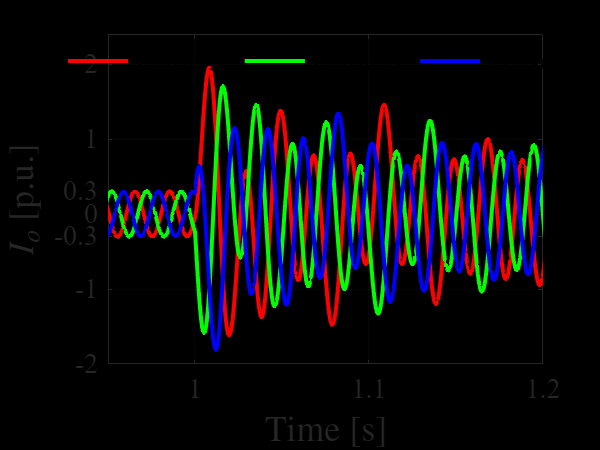

fig = figure; 
set(fig, figopts);

t = Vo.time;
fsample = 1/Ts_Power;

grid on
hold on

plot(t(9e4: 20e4), Io.signals.values(9e4: 20e4, 1), LineWidth=2, Color='r')
plot(t(9e4: 20e4), Io.signals.values(9e4: 20e4, 2), LineWidth=2, Color='g')
plot(t(9e4: 20e4), Io.signals.values(9e4: 20e4, 3), LineWidth=2, Color='b')
ylim([-2 2.4])
xlim([.95 1.2])
yticks([-2 -1 -.3 0 .3 1 2])
lgd = legend(["Phase A", "Phase B", "Phase C"], NumColumns=3);
xlabel("Time [s]")
ylabel("$I_o$ [p.u.]")

set(lgd, lgdopts);
ax = gca;
set(ax, axopts);
set(ax.XLabel, XLabelopts);
set(ax.YLabel, YLabelopts);

exportgraphics(gcf, "./fig/ss/Io_frt.eps")

### Vsm averaging SMs capacitor voltage

% fig = figure;
% set(fig, figopts);
% 
% t = Vsm.time(9.6e4: 10e4);
% data = Vsm.signals.values(9.6e4: 10e4, :);
% 
% plot(t, data, LineWidth=.5);
% ylim([4730 4860]);
% grid on
% xlabel("Time [s]");
% ylabel("Voltage [V]");
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% exportgraphics(gcf, "./fig/ss/Vsm.eps", ContentType="vector")

### circulating current elimination validation

% fig = figure;
% set(fig, figopts);
% tiledlayout(2, 1);
% 
% ax1 = nexttile;  % with; waveform
% t = Ipa1.time(9.6e4: 10e4);
% data = Ipa1.signals.values(9.6e4: 10e4, :);
% 
% plot(t, data, LineWidth=2, Color='k');
% grid on
% ylim([-200 360])
% yticks([-170 0 345])
% xlabel("Time [s]");
% ylabel("Output Current [A]");
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% set(lgd, lgdopts);
% 
% ax2 = nexttile;  % with; spectrum
% [ft, P1] = calcSpectrum(data, fsample);
% 
% bar(ft, P1/max(P1), 'k')
% grid on
% xlim([0 1000])
% xlabel("Frequency [Hz]")
% ylabel("Amplitude [p.u.]")
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% exportgraphics(gcf, "./fig/ss/Iap_with_cir.eps", ContentType="vector")

% fig = figure;
% set(fig, figopts);
% tiledlayout(2, 1);
% 
% ax1 = nexttile;  % without; waveform
% t = Ipa2.time(9.6e4: 10e4);
% data = Ipa2.signals.values(9.6e4: 10e4, :);
% 
% plot(t, data, LineWidth=2, Color='k');
% grid on
% ylim([-225 310])
% yticks([-215 0 295])
% xlabel("Time [s]");
% ylabel("Output Current [A]");
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% set(lgd, lgdopts);
% 
% ax2 = nexttile;  % without; spectrum
% [ft, P1] = calcSpectrum(data, fsample);
% 
% bar(ft, P1/max(P1), 'k')
% grid on
% xlim([0 1000])
% yticks([0 .2 1])
% xlabel("Frequency [Hz]")
% ylabel("Amplitude [p.u.]")
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% exportgraphics(gcf, "./fig/ss/Iap_without_cir.eps", ContentType="vector")

## Islanded mode

### output voltage and its spectrum

% fig = figure; 
% set(fig, figopts);
% 
% tiledlayout(2, 1)
% 
% t = Vo.time;
% fsample = 1/Ts_Power;
% 
% ax1 = nexttile;  % Vo
% grid on
% hold on
% 
% plot(t(19.6e4: 20e4), Vo.signals.values(19.6e4: 20e4, 1), LineWidth=2, Color='r')
% plot(t(19.6e4: 20e4), Vo.signals.values(19.6e4: 20e4, 2), LineWidth=2, Color='g')
% plot(t(19.6e4: 20e4), Vo.signals.values(19.6e4: 20e4, 3), LineWidth=2, Color='b')
% ylim([-1.2 1.55])
% xlim([1.96 2.0])
% lgd = legend(["Phase A", "Phase B", "Phase C"], NumColumns=3);
% xlabel("Time [s]")
% ylabel("$V_o$ [p.u.]")
% 
% set(lgd, lgdopts);
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% ax2 = nexttile;  % spectrum
% grid on
% hold on
% 
% [ft, P1] = calcSpectrum(Vo.signals.values(19.6e4: 20e4-1, 1), fsample);
% 
% bar(ft, P1, 'k')
% xlim([0 1500])
% xlabel("Frequency [Hz]")
% ylabel("Amplitude [p.u.]")
% ylim([0 1.02])
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% thd = calcTHD(P1, ft, 1e6);
% annotation("textarrow", [.25 .2], [.35 .32], String="$0.95\,$p.u.", Interpreter="latex", FontSize=14)
% text(800, .7, "THD = $"+sprintf("%.1f",thd*100)+"$\%", Interpreter="latex", FontSize=14)
% exportgraphics(gcf, "./fig/islanded/Vo.eps")

### output current and its spectrum

% fig = figure; 
% set(fig, figopts);
% 
% tiledlayout(2, 1)
% 
% t = Vo.time;
% fsample = 1/Ts_Power;
% 
% ax1 = nexttile;  % Io
% grid on
% hold on
% 
% plot(t(19.6e4: 20e4), Io.signals.values(19.6e4: 20e4, 1), LineWidth=2, Color='r')
% plot(t(19.6e4: 20e4), Io.signals.values(19.6e4: 20e4, 2), LineWidth=2, Color='g')
% plot(t(19.6e4: 20e4), Io.signals.values(19.6e4: 20e4, 3), LineWidth=2, Color='b')
% ylim([-.42 .55])
% xlim([1.96 2])
% lgd = legend(["Phase A", "Phase B", "Phase C"], NumColumns=3);
% xlabel("Time [s]")
% ylabel("$I_o$ [p.u.]")
% 
% set(lgd, lgdopts);
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% ax2 = nexttile;  % spectrum
% grid on
% hold on
% 
% [ft, P1] = calcSpectrum(Io.signals.values(19.6e4: 20e4-1, 1), fsample);
% 
% bar(ft, P1, 'k')
% xlim([0 1500])
% xlabel("Frequency [Hz]")
% ylabel("Amplitude [p.u.]")
% ylim([0 .4])
% yticks([0 .4])
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% thd = calcTHD(P1, ft, 1e5);
% annotation("textarrow", [.25 .2], [.35 .32], String="$0.37\,$p.u.", Interpreter="latex", FontSize=14)
% text(800, .04, "THD = $"+sprintf("%.1f",thd*100)+"$\%", Interpreter="latex", FontSize=14)
% exportgraphics(gcf, "./fig/islanded/Io.eps")

### active power vs frequency

% fig = figure;
% set(fig, figopts);
% 
% tiledlayout(2, 1);
% 
% ax1 = nexttile;  % freq
% t = freq.time;
% data = freq.signals.values;
% 
% plot(t, data, LineWidth=2, Color='k');
% grid on
% hold on
% plot(t(11e4: 20e4), 50.022*ones(9e4+1, 1), LineWidth=2, Color='k', LineStyle="--")
% ylim([49.94 50.16]);
% yticks([49.95, 50, 50.13]);
% ytickformat("%.2f");
% % xlabel("Time [s]");
% ylabel("Frequency [Hz]");
% annotation("textarrow", [.75 .7], [.8 .74], String="$50.02\,$Hz", Interpreter="latex", FontSize=14)
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% ax2 = nexttile;  % active power
% data = P.signals.values;
% 
% plot(t, data, LineWidth=2, Color='k');
% grid on
% hold on
% plot(t, .3*ones(length(t), 1), LineWidth=2, Color='k', LineStyle=":")
% plot(t(11e4: 20e4), 0.27*ones(9e4+1, 1), LineWidth=2, Color='k', LineStyle="--")
% 
% ylim([0 .42]);
% yticks([0.05 .3]);
% lgd = legend(ax2, ["Real value", "Reference"], NumColumns=2);
% set(lgd, lgdopts);
% xlabel("Time [s]");
% ylabel("Active Power [p.u.]");
% annotation("textarrow", [.75 .7], [.3 .34], String="$0.27\,$p.u.", Interpreter="latex", FontSize=14)
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% set(lgd, lgdopts);
% 
% linkaxes([ax1 ax2], 'x');
% exportgraphics(gcf, "./fig/islanded/freq_P.eps")

### Reactive power vs amplitude

% fig = figure;
% set(fig, figopts);
% 
% tiledlayout(2, 1);
% 
% ax1 = nexttile;  % amplitude
% t = Vabs.time;
% data = Vabs.signals.values;
% grid on
% hold on
% plot(t, data, LineWidth=2, Color='k');
% ylim([.92 1.07]);
% yticks([.95 1  1.05]);
% % xlabel("Time [s]");
% ylabel("$|V_o|$ [p.u.]");
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% ax2 = nexttile;  % reactive power
% data = Q.signals.values;
% grid on
% hold on
% 
% plot(t, data, LineWidth=2, Color='k');
% plot(t, zeros(length(t), 1), LineWidth=2, Color='k', LineStyle="--")
% ylim([0 .35]);
% yticks([0 .22]);
% lgd = legend(ax2, ["Real value", "Reference"], NumColumns=2);
% 
% xlabel("Time [s]");
% ylabel("Reactive Power [p.u.]");
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% set(lgd, lgdopts);
% 
% linkaxes([ax1 ax2], 'x');
% exportgraphics(gcf, "./fig/islanded/ampl_Q.eps")

## Strong grid

### active power vs frequency

% fig = figure;
% set(fig, figopts);
% 
% tiledlayout(2, 1);
% 
% ax1 = nexttile;  % freq
% t = freq.time;
% data = freq.signals.values;
% grid on
% hold on
% plot(t, data, LineWidth=2, Color='k');
% xlim([0 .3]);
% % yticks([49.87, 50, 50.18]);
% % xlabel("Time [s]");
% ylabel("Frequency [Hz]");
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% ax2 = nexttile;  % active power
% data = P.signals.values;
% grid on
% hold on
% 
% plot(t, data, LineWidth=2, Color='k');
% plot(t, .3*ones(length(t), 1), LineWidth=2, Color='k', LineStyle="--")
% xlim([0 .3]);
% % yticks([ 0 .3 .64]);
% ytickformat("%.2f");
% lgd = legend(ax2, ["Real value", "Reference"], NumColumns=2);
% set(lgd, lgdopts);
% xlabel("Time [s]");
% ylabel("Active Power [p.u.]");
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% set(lgd, lgdopts);
% 
% linkaxes([ax1 ax2], 'x');
% exportgraphics(gcf, "./fig/strong/freq_P.eps")

### Reactive power vs amplitude

% fig = figure;
% set(fig, figopts);
% 
% tiledlayout(2, 1);
% 
% ax1 = nexttile;  % amplitude
% t = Vabs.time;
% data = Vabs.signals.values;
% grid on
% hold on
% plot(t, data, LineWidth=2, Color='k');
% xlim([0 .3]);
% % yticks([.65 1 1.05]);
% ytickformat("%.2f")
% % xlabel("Time [s]");
% ylabel("$|V_o|$ [p.u.]");
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% 
% ax2 = nexttile;  % reactive power
% data = Q.signals.values;
% grid on
% hold on
% 
% plot(t, data, LineWidth=2, Color='k');
% plot(t, .1*ones(length(t), 1), LineWidth=2, Color='k', LineStyle="--")
% xlim([0 .3]);
% % yticks([0.1 .45 1.49]);
% ytickformat("%.2f");
% lgd = legend(ax2, ["Real value", "Reference"], NumColumns=2);
% 
% xlabel("Time [s]");
% ylabel("Reactive Power [p.u.]");
% 
% ax = gca;
% set(ax, axopts);
% set(ax.XLabel, XLabelopts);
% set(ax.YLabel, YLabelopts);
% set(lgd, lgdopts);
% 
% linkaxes([ax1 ax2], 'x');
% exportgraphics(gcf, "./fig/strong/ampl_Q.eps")